% Expand Fourier series of periodic functions f(x) with period T, 
% given on the indicated intervals:
% f(x)=x^2; T=2*pi; [0;pi]
% Continue f(x) on a stretch [-pi;0] in an odd manner

clear
pi1=pi;
syms x real;
syms pi;
f(x)=piecewise(-pi<=x<=0,-x^2,0<=x<=pi,x^2)

$$f(x) = \left\{ \begin{array}{cl} -x^{2} & \text{ if }x\in \left[-\pi ,0\right]\\ x^{2} & \text{ if }x\in \left[0,\pi \right] \end{array}\right.$$


syms m integer;
[a0,a(m),b(m),abf(m)]=fourierseries(f)

$$a0 = 0$$

$$a(m) = 0$$

$$b(m) = -\frac{2\,\left({\left(-1\right)}^{m}\,m^{2}\,\pi^{2}-2\,{\left(-1\right)}^{m}+2\right)}{m^{3}\,\pi }$$

$$abf(m) = -\frac{2\,\sin\left(m\,x\right)\,\left({\left(-1\right)}^{m}\,m^{2}\,\pi^{2}-2\,{\left(-1\right)}^{m}+2\right)}{m^{3}\,\pi }$$

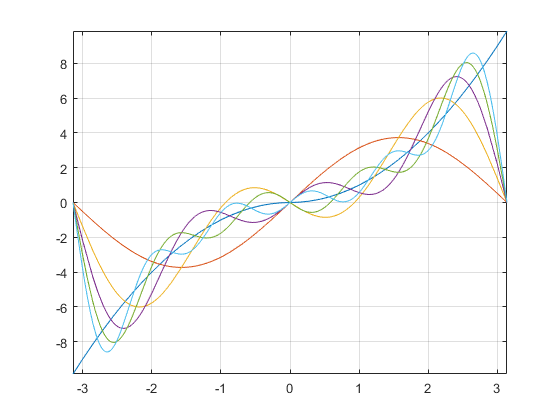


fplot(f(x),[-pi1 pi1]);
grid on
hold on

f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-pi1 pi1])
    grid on
end
hold off


a0/2

$$ans = 0$$

% 0
ft=[m1;a1;b1;abf1];
ft'

$$ans = \begin{array}{l} \left(\begin{array}{cccc} 1 & 0 & \frac{2\,\left(\pi^{2}-4\right)}{\pi } & \frac{2\,\sin\left(x\right)\,\left(\pi^{2}-4\right)}{\pi }\\ 2 & 0 & -\pi & -\pi \,\sin\left(2\,x\right)\\ 3 & 0 & \frac{2\,\sigma_{2}}{27\,\pi } & \frac{2\,\sin\left(3\,x\right)\,\sigma_{2}}{27\,\pi }\\ 4 & 0 & -\frac{\pi }{2} & -\frac{\pi \,\sin\left(4\,x\right)}{2}\\ 5 & 0 & \frac{2\,\sigma_{1}}{125\,\pi } & \frac{2\,\sin\left(5\,x\right)\,\sigma_{1}}{125\,\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=25\,\pi^{2}-4\\ \sigma_{2}=9\,\pi^{2}-4 \end{array}$$

% [ 1, 0,        (2*pi^2 - 8)/pi,          (sin(x)*(2*pi^2 - 8))/pi]
% [ 2, 0,                    -pi,                      -pi*sin(2*x)]
% [ 3, 0,  (18*pi^2 - 8)/(27*pi),  (sin(3*x)*(18*pi^2 - 8))/(27*pi)]
% [ 4, 0,                  -pi/2,                  -(pi*sin(4*x))/2]
% [ 5, 0, (50*pi^2 - 8)/(125*pi), (sin(5*x)*(50*pi^2 - 8))/(125*pi)]